# lora link budget analysis

Old code to calculate channel parameters such as doppler and snr

## ground station transmitter:

according to [https://ieeexplore.ieee.org/document/10040628,](https://ieeexplore.ieee.org/document/10040628,) Lacuna uses the LR1110 chip for their satellites

SX126X: https://www.mouser.be/new/semtech/semtech-sx1268-transceiver/

Ptx max 22dBm

PA 14 dBm =gain?

sensitivity -148 dBm (SF12 sensitivty=-134dBm)

modulations: FSK and lora

Programmable bit rate up to 62.5 kbps LoRa and 300kbps FSK

SX127X https://www.mouser.be/new/semtech/semtech-sx1276-transceiver/

Ptx max 20 dB

LR1110 https://www.mouser.be/new/semtech/semtech-lr1110-rf-transceiver/

Ptx max 22 dBm

 receives 125 kHz channels at SF12

can transmit at 14 or 22 dBm at 868 MHz

clear;
%sat characteristics
semiMajorAxis = 550000+6371000;
eccentricity = 0;
inclination = 0; 
rightAscensionOfAscendingNode = 0; 
argumentOfPeriapsis = 0; 
trueAnomaly = 0; 

% Calculate orbital period
mu = 3.986e14; % Gravitational parameter of Earth (m^3/s^2) = G*M
orbitalPeriod = 2 * pi * sqrt((semiMajorAxis^3) / mu)

orbitalPeriod = 5.7301e+03


startTime = datetime(2020,5,1,11,36,0);
stopTime = startTime + seconds(2*orbitalPeriod);
sampleTime=30;
timePoints = startTime:seconds(sampleTime):stopTime;

sc = satelliteScenario(startTime,stopTime,sampleTime);
lat = 0;
lon = 0;
minElevationAngle=0;
gs = groundStation(sc,lat,lon,"MinElevationAngle",minElevationAngle);


sat = satellite(sc,semiMajorAxis,eccentricity,inclination, rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly);


names = sat.Name + " Camera";
cam = conicalSensor(sat,"Name",names,"MaxViewAngle",179);
pointAt(sat,gs);
ac = access(cam,gs);

fov = fieldOfView(cam);

%show(sat)

accessIntervals(ac)

ans = 2×8 table
           Source                 Target          IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ____________________    __________________    ______________    ____________________    ____________________    ________    __________    ________

    "Satellite 2 Camera"    "Ground station 1"          1           01-May-2020 11:39:30    01-May-2020 11:52:00      750           1            1    
    "Satellite 2 Camera"    "Ground station 1"          2           01-May-2020 13:21:30    01-May-2020 13:34:00      750           2            2    


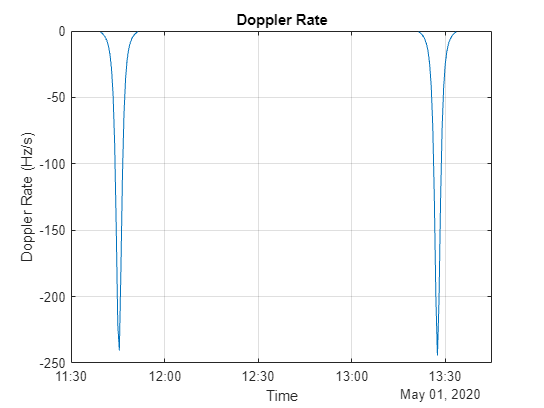

elevationRangeMatrix=0;
s = accessStatus(ac);
for i = 1:numel(timePoints)
    % Get elevation angle etc between satellite and ground station
    [azimuth,elevation,range] = aer(sat,gs,startTime+seconds((i-1)*sampleTime));
    elevationRangeMatrix(i,1)=elevation;
    elevationRangeMatrix(i,2)=range;
    elevationRangeMatrix(i,3)=((i-1)*sampleTime);
    
    % if(s(i)==1)
    % 
    %     counter=counter+1;
    % else
    %     elevationRangeMatrix(i,1)=0;
    %     elevationRangeMatrix(i,2)=0;
    %     elevationRangeMatrix(i,3)=((i-1)*sampleTime);
    % end
end
elevationRangeMatrix(:,4)=s(1:numel(s)-1);

hold off

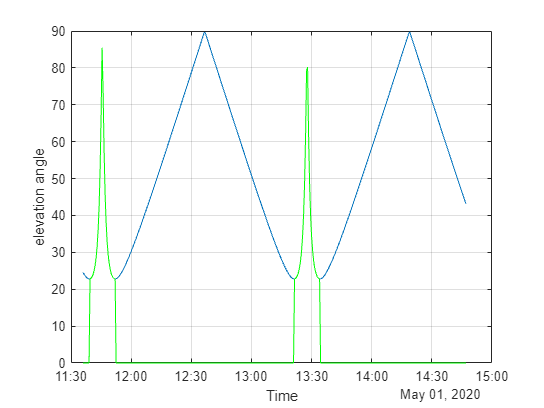

plot(timePoints,-1*elevationRangeMatrix(:,1))
hold on
plot(timePoints,-1*elevationRangeMatrix(:,1).*elevationRangeMatrix(:,4),"green")
grid on
ylim([0 90])
xlabel("Time");
ylabel("elevation angle");
hold off


el_min=min(-1*elevationRangeMatrix(:,1))

el_min = 22.7834

el_max=max(-1*elevationRangeMatrix(:,1))

el_max = 89.7292

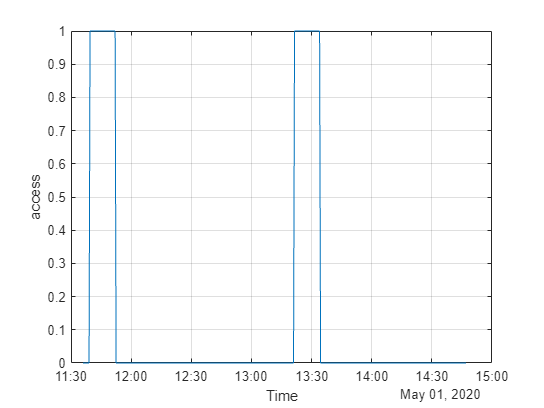



plot(timePoints,elevationRangeMatrix(:,4))
grid on
xlabel("Time");
ylabel("access");

hold off

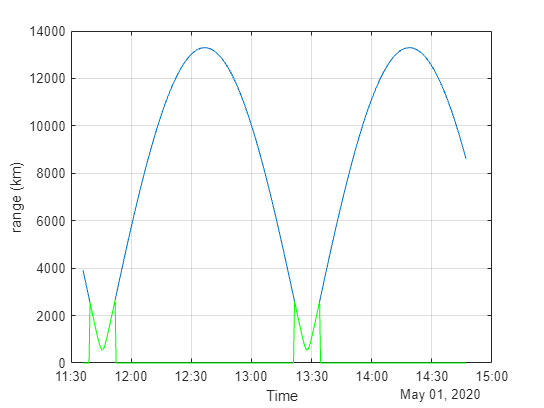

plot(timePoints,elevationRangeMatrix(:,2)/1000)
hold on
plot(timePoints,elevationRangeMatrix(:,2)/1000.*elevationRangeMatrix(:,4),"green")
grid on;
xlabel("Time");
ylabel("range (km)");
hold off


range_min=min(elevationRangeMatrix(:,2))

range_min = 5.4152e+05

range_max=max(elevationRangeMatrix(:,2))

range_max = 1.3296e+07

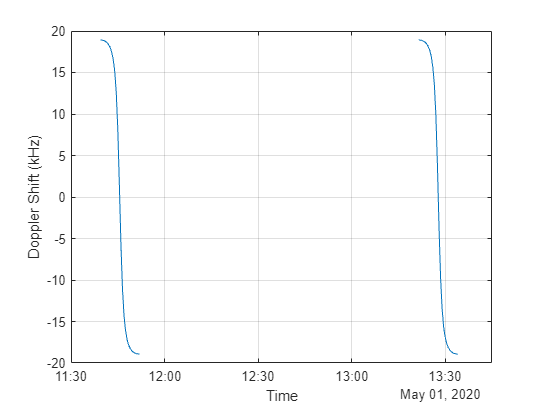


% Emitted carrier frequency in Hz
fc = 868e6;
% Calculate Doppler shift and get additional information about Doppler. The
% Doppler information output contains relative velocity and Doppler rate.
% The dopplershift function internally performs access analysis and returns
% NaN whenever there is no access.
[fShift,time,dopplerInfo] = dopplershift(sat,gs,Frequency=fc);
plot(time,fShift(1,:)/1e3)                        % Plot in kHz
xlabel("Time")
ylabel("Doppler Shift (kHz)")
grid on

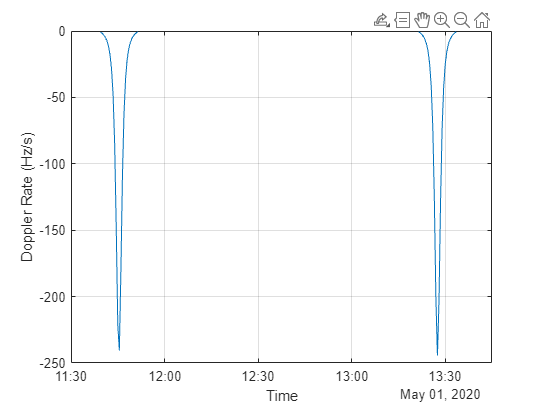


plot(time(1:end-1),dopplerInfo.DopplerRate(1,:))  % Plot in Hz/s
xlabel("Time")
ylabel("Doppler Rate (Hz/s)")
grid on

% [azimuth1,elevation1,range1] = aer(sat,gs,datetime(2020,5,1,11,45,0))
% [azimuth2,elevation2,range2] = aer(sat,gs,datetime(2020,5,1,12,38,0))

## calculate link margin lora

%lora sens=-174+10*log10(BW)+SNR
%Tx characteristics (ground)
Pt=22;
Gt=0;
%Rx characteristics (satellite)
Gr=0;
GTR=-18.6; 
NF=9;
%Tn=;%noise temp
%Tsys=Tn+
%GTR=Gr-Nf;
%lora characteristics
f=868e6;%freq
SF=12;%spreading factor
BW=125e3;%bandwidth
CR=4/6;%code rate (useful/parity symbols)
Ts=(2^SF)/BW;
Rb=CR*SF/Ts%bitrate

Rb = 244.1406

Tb=1/Rb;

%link characteristics
d=550e3;%distance
%ToDo vary distance over trajectory
c=2.998e8;
Lp=20*log10(d)+20*log10(f)+20*log10(4*pi/c)%free space path loss 

Lp = 146.0252

L=Lp;%+....
%ToDo vary loss over trajectory

sens=-135;
EIRP=Pt+Gt

EIRP = 22

RSSI=EIRP+Gr-L

RSSI = -124.0252


%SNR=RSSI-Noise
Ml=sens-RSSI

Ml = -10.9748



CNR0=EIRP+GTR-L+228.6

CNR0 = 85.9748

EBR0=CNR0-10*log10(Rb)

EBR0 = 62.0984

## NBioT

%Tx characteristics (ground)
Pt=22;
Gt=14;
%Rx characteristics (satellite)
Gr=0;
GTR=-18.6; 
%Tn=;%noise temp
%Tsys=Tn+
%GTR=Gr-Nf;

%link characteristics
f=868e6;%frequency
d=550e3;%distance
%ToDo vary distance over trajectory
c=2.998e8;
Lp=20*log(d)+20*log(f)+20*log(4*pi/c)%free space path loss

Lp = 336.2355

L=Lp;
%ToDo vary loss over trajectory

sens=-141;
EIRP=Pt+Gt

EIRP = 36

RSSI=EIRP+Gr-L

RSSI = -300.2355


SNR=RSSI-L

SNR = -636.4710

Ml=sens+RSSI

Ml = -441.2355



CNR0=EIRP+GTR-L+228.6

CNR0 = -90.2355

EBR0=CNR0/Rb

Unrecognized function or variable 'Rb'.

## BER

%https://www.researchgate.net/publication/366847808_Analysis_Of_The_Energy_Per_Bit_To_Noise_Power_Spectral_Density_And_Operating_System_Margin_For_Lora-Based_Wireless_Sensor_Network
%https://ieeexplore.ieee.org/document/7500415